%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ENG EC 503 (Ishwar) Fall 2023
% HW 6.3
% <Demetrios Kechris dkechris@bu.edu>
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

load("iris.mat")

%%%%%%%%%%%% Part(a) %%%%%%%%%%%%%%%%%%
disp("Part A")

Part A



% (i) Histogram of labels
X_label_total = [X_data_train; X_data_test];
Y_label_total = [Y_label_train; Y_label_test];

C = categorical(Y_label_train,[1 2 3],{'1','2','3'})

C = 105×1 categorical array
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 


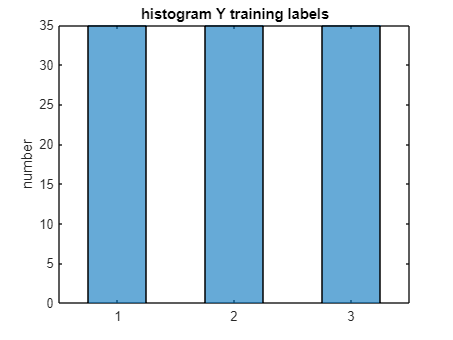

histogram(C, BarWidth=.5)
title("histogram Y training labels")
ylabel("number")


C = categorical(Y_label_test,[1 2 3],{'1','2','3'})

C = 45×1 categorical array
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 


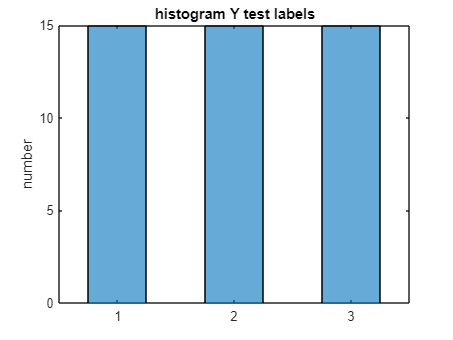

histogram(C, BarWidth=.5)
title("histogram Y test labels")
ylabel("number")


C = categorical(Y_label_total,[1 2 3],{'1','2','3'})

C = 150×1 categorical array
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 


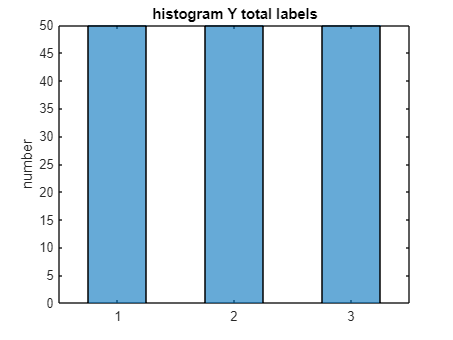

histogram(C, BarWidth=.5)
title("histogram Y total labels")
ylabel("number")


n = size(X_data_train,1)

n = 105

unique_lables = unique(Y_label_train)

unique_lables =      1
     2
     3


m = size(unique_lables,1)

m = 3


% Retrieve the locations of the edges and the heights of the bars.

% (ii) Correlation Coefficients
train_feature1 = X_data_train(:,1);
train_feature2 = X_data_train(:,2);
train_feature3 = X_data_train(:,3);
train_feature4 = X_data_train(:,4);

emp_corr_coeff_12 = empCorrCoeff(train_feature1,train_feature2)

emp_corr_coeff_12 =     1.8855   -0.1571
   -0.1571    0.5304


emp_corr_coeff_13 = empCorrCoeff(train_feature1,train_feature3)

emp_corr_coeff_13 =     0.4663    0.8917
    0.8917    2.1445


emp_corr_coeff_14 = empCorrCoeff(train_feature1,train_feature4)

emp_corr_coeff_14 =     1.0511    0.8521
    0.8521    0.9514


emp_corr_coeff_23 = empCorrCoeff(train_feature2,train_feature3)

emp_corr_coeff_23 =     0.2473   -0.4136
   -0.4136    4.0434


emp_corr_coeff_24 = empCorrCoeff(train_feature2,train_feature4)

emp_corr_coeff_24 =     0.5575   -0.3277
   -0.3277    1.7938


emp_corr_coeff_34 = empCorrCoeff(train_feature3,train_feature4)

emp_corr_coeff_34 =     2.2541    0.9671
    0.9671    0.4436


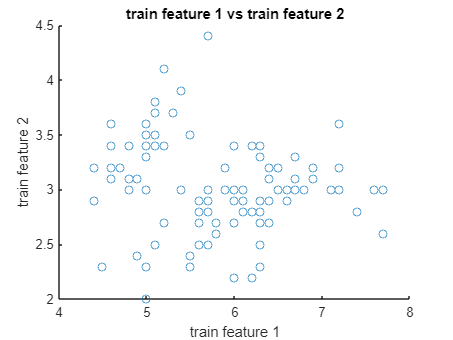



% (iii) 2D scatter plots of all pairs of features
figure(1)
scatter(train_feature1,train_feature2)
title("train feature 1 vs train feature 2")
xlabel("train feature 1")
ylabel("train feature 2")

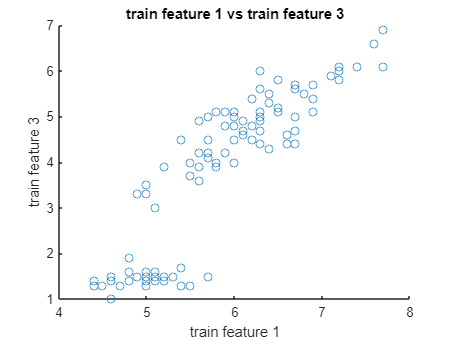


figure(2)
scatter(train_feature1,train_feature3)
title("train feature 1 vs train feature 3")
xlabel("train feature 1")
ylabel("train feature 3")

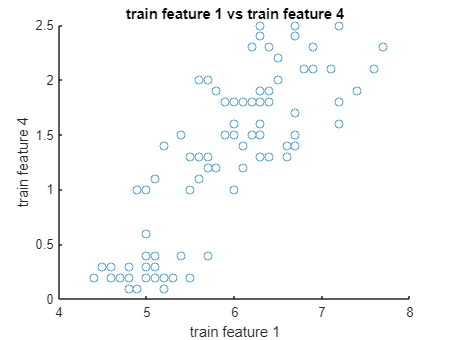


figure(3)
scatter(train_feature1,train_feature4)
title("train feature 1 vs train feature 4")
xlabel("train feature 1")
ylabel("train feature 4")

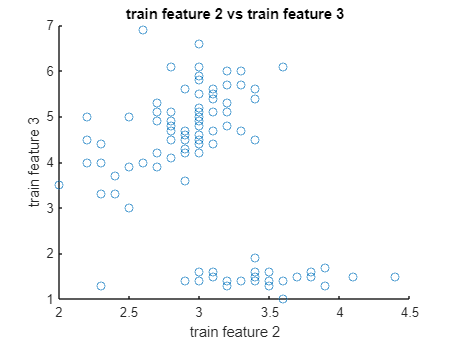


figure(4)
scatter(train_feature2,train_feature3)
title("train feature 2 vs train feature 3")
xlabel("train feature 2")
ylabel("train feature 3")

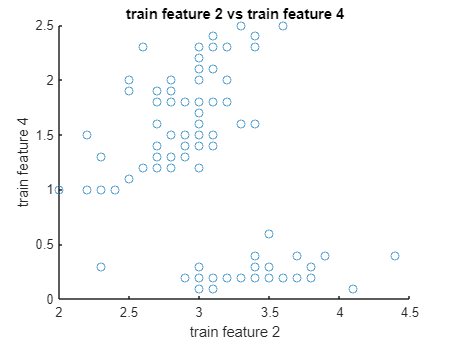


figure(5)
scatter(train_feature2,train_feature4)
title("train feature 2 vs train feature 4")
xlabel("train feature 2")
ylabel("train feature 4")

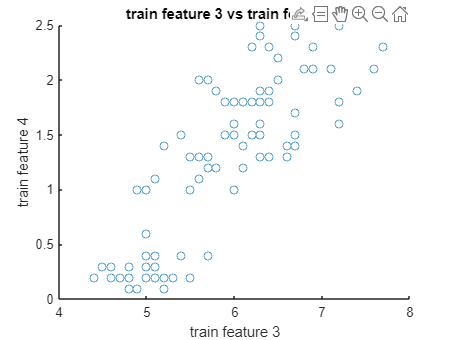


figure(6)
scatter(train_feature1,train_feature4)
title("train feature 3 vs train feature 4")
xlabel("train feature 3")
ylabel("train feature 4")



    
%%%%%%%%%% Training logistic regression with SGD %%%%%%%%%%%%
% use discussion codet_max = 10000
% initialize to 0
t_max = 10000;
theta = zeros(size(X_data_train,2)+1,m);
theta_ema = zeros(1,m);
v = zeros(size(X_data_train,2)+1,m);
lambda = .1;
x_ext = [X_data_train ones(size(X_data_train,1),1)];
theta_loss_norm_train = zeros(1,t_max/20);
theta_ema_loss_norm_train = zeros(1,t_max/20);
theta_loss_norm_test = zeros(1,t_max/20);
theta_ema_loss_norm_test = zeros(1,t_max/20);
theta_CCR_train = zeros(1,t_max/20);
theta_ema_CCR_train = zeros(1,t_max/20);
theta_CCR_test = zeros(1,t_max/20);
theta_ema_CCR_test = zeros(1,t_max/20);

for t=1:1:t_max
    j = randi(n);
    xj = x_ext(j,:);
    st = .01/t;
    
    likelihood = exp(theta'*xj') / sum(exp(theta'*xj')); % m * 1 vector, sum equals 1
    one_hot_label = zeros(m, 1);
    one_hot_label(Y_label_train(j)) = 1; % m * 1 one hot vector
    % Get the gradient for the regularized weights
    gradient = 2 * lambda * theta + n * xj' * (likelihood - one_hot_label)'; %(d+1) * m
    % Update parameter
    theta = theta - st * gradient;
    theta_ema = theta_ema*0.99 + theta*0.01;

    %test functions
    if mod(t, 20) == 0
        theta_loss_norm_train(1,t/20) = c_log_loss(x_ext, Y_label_train, theta, lambda) / n;
        theta_ema_loss_norm_train(1,t/20) = c_log_loss(x_ext, Y_label_train, theta_ema, lambda) / n;
        theta_loss_norm_test(1,t/20) = c_log_loss([X_data_test ones(size(X_data_test,1),1)], Y_label_test, theta, lambda) / n;
        theta_ema_loss_norm_test(1,t/20) = c_log_loss([X_data_test ones(size(X_data_test,1),1)], Y_label_test, theta_ema, lambda) / n;
        theta_CCR_train(1,t/20) = CCR(X_data_train, Y_label_train, theta);
        theta_ema_CCR_train(1,t/20) = CCR(X_data_train, Y_label_train, theta_ema);
        theta_CCR_test(1,t/20) = CCR(X_data_train, Y_label_train, theta);
        theta_ema_CCR_test(1,t/20) = CCR(X_data_train, Y_label_train, theta_ema);
    end    

end

disp("theta + theta_ems")

theta + theta_ems


theta

theta =     0.5410    0.1377   -0.6787
    1.1695   -0.2100   -0.9595
   -1.8853    0.3406    1.5447
   -0.7350   -0.2309    0.9659
    0.2931    0.0918   -0.3849


theta_ema

theta_ema =     0.5410    0.1357   -0.6768
    1.1694   -0.2109   -0.9586
   -1.8851    0.3395    1.5456
   -0.7349   -0.2310    0.9659
    0.2931    0.0914   -0.3845



disp("theta + theta_ems")

theta + theta_ems


theta_loss_norm_train

theta_loss_norm_train =     0.7417    0.6733    0.3709    0.3582    0.4165    0.3343    0.3312    0.3736    0.3620    0.3603    0.3261    0.3385    0.3560    0.3536    0.3218    0.3211    0.3357    0.3314    0.3245    0.3187    0.3184    0.3187    0.3200    0.3176    0.3174    0.3164    0.3197    0.3159    0.3156    0.3262    0.3188    0.3157    0.3146    0.3149    0.3204    0.3211    0.3192    0.3257    0.3338    0.3125    0.3180    0.3210    0.3167    0.3118    0.3123    0.3137    0.3126    0.3202    0.3189    0.3119




%%%%%%%%%%%%%% Part(b) %%%%%%%%%%%%%%%%%
disp("Part B")

Part B


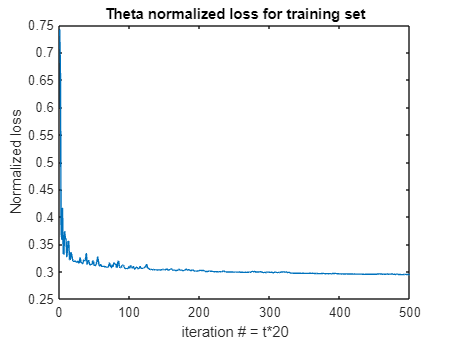

t_array = 1:20:t_max;

figure
plot(theta_loss_norm_train)
xlabel("iteration # = t*20")
title("Theta normalized loss for training set")
ylabel("Normalized loss")

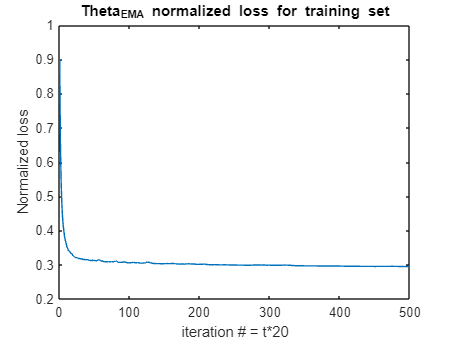


figure
plot(theta_ema_loss_norm_train)
xlabel("iteration # = t*20")
title("Theta_EMA normalized loss for training set")
ylabel("Normalized loss")


%%%%%%%%%%%%% Part(c) %%%%%%%%%%%%%%%%%%
disp("Part C")

Part C


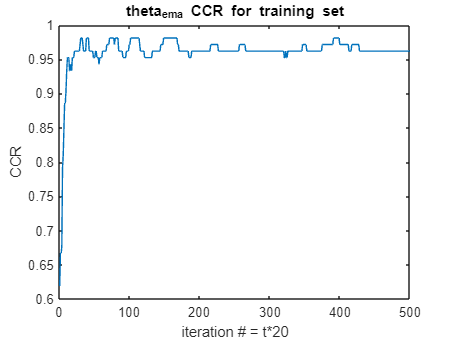

figure
plot(theta_ema_CCR_train)
xlabel("iteration # = t*20")
title("theta_ema CCR for training set")
ylabel("CCR")

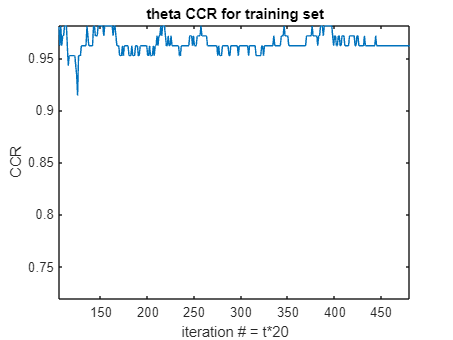


figure
plot(theta_CCR_train)
xlabel("iteration # = t*20")
title("theta CCR for training set")
ylabel("CCR")


%%%%%%%%%%%%% Part(d) %%%%%%%%%%%%%%%%%%
disp("Part D")

Part D


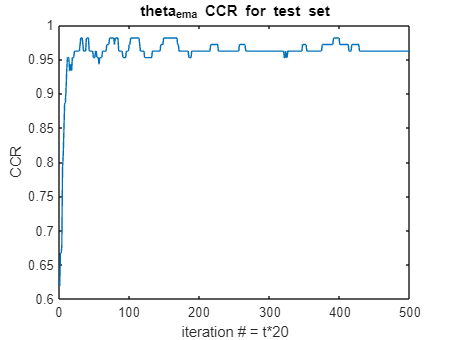

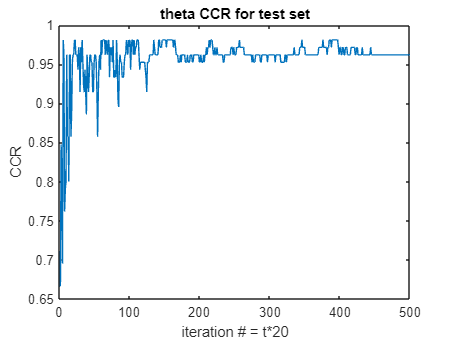

figure
figure
plot(theta_CCR_test)
xlabel("iteration # = t*20")
title("theta CCR for test set")
ylabel("CCR")

plot(theta_ema_CCR_test)
xlabel("iteration # = t*20")
title("theta_ema CCR for test set")
ylabel("CCR")


%%%%%%%%%%%%% Part(e) %%%%%%%%%%%%%%%%%%
disp("Part E")

Part E


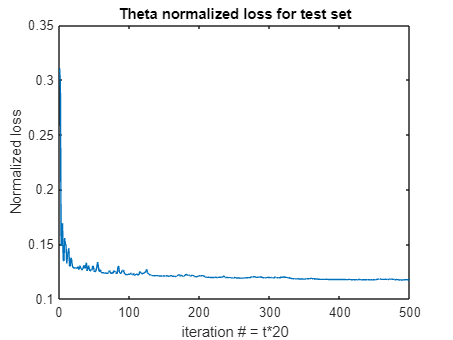

figure
plot(theta_loss_norm_test)
xlabel("iteration # = t*20")
title("Theta normalized loss for test set")
ylabel("Normalized loss")

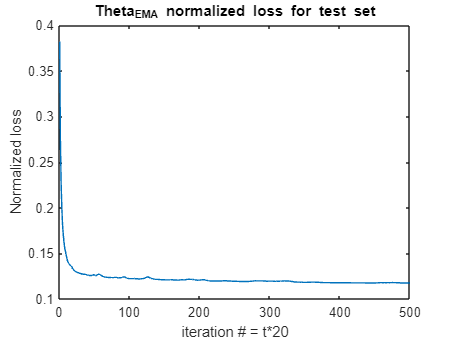


figure
plot(theta_ema_loss_norm_test)
xlabel("iteration # = t*20")
title("Theta_EMA normalized loss for test set")
ylabel("Normalized loss")


%%%%%%%%%%%%% Part(f) %%%%%%%%%%%%%%%%%%
% (i)
disp('(f)(i): Theta:')

(f)(i): Theta:


theta

theta =     0.5410    0.1377   -0.6787
    1.1695   -0.2100   -0.9595
   -1.8853    0.3406    1.5447
   -0.7350   -0.2309    0.9659
    0.2931    0.0918   -0.3849


disp('(f)(i): Theta_ema:')

(f)(i): Theta_ema:


theta_ema

theta_ema =     0.5410    0.1357   -0.6768
    1.1694   -0.2109   -0.9586
   -1.8851    0.3395    1.5456
   -0.7349   -0.2310    0.9659
    0.2931    0.0914   -0.3845



% (ii)
disp('(f)(ii): Theta Training CCR:')

(f)(ii): Theta Training CCR:


CCR(X_data_train, Y_label_train, theta)

ans = 0.9619

disp('(f)(ii): Theta_ema Training CCR:')

(f)(ii): Theta_ema Training CCR:


CCR(X_data_train, Y_label_train, theta_ema)

ans = 0.9619

        
% (iii)
disp('(f)(iii): Theta Test CCR:')

(f)(iii): Theta Test CCR:


CCR(X_data_train, Y_label_train, theta)

ans = 0.9619

disp('(f)(iii): Theta_ema Test CCR:')

(f)(iii): Theta_ema Test CCR:


CCR(X_data_train, Y_label_train, theta_ema)

ans = 0.9619



% (iv)
disp('(f)(iv): Theta Training confusion matrix:')

(f)(iv): Theta Training confusion matrix:


disp('rows are the predicted label, columns are actual label')

rows are the predicted label, columns are actual label


conf_mat(X_data_train, Y_label_train, theta)

ans =     35     0     0
     0    31     0
     0     4    35


disp('(f)(iv): Theta_ema Training confusion matrix:')

(f)(iv): Theta_ema Training confusion matrix:


disp('rows are the predicted label, columns are actual label')

rows are the predicted label, columns are actual label


conf_mat(X_data_train, Y_label_train, theta_ema)

ans =     35     0     0
     0    31     0
     0     4    35




% (v)
disp('(f)(v): Theta Test confusion matrix:')

(f)(v): Theta Test confusion matrix:


disp('rows are the predicted label, columns are actual label')

rows are the predicted label, columns are actual label


conf_mat(X_data_test, Y_label_test, theta)

ans =     15     0     0
     0    14     0
     0     1    15


disp('(f)(v): Theta_ema Test confusion matrix:')

(f)(v): Theta_ema Test confusion matrix:


disp('rows are the predicted label, columns are actual label')

rows are the predicted label, columns are actual label


conf_mat(X_data_test, Y_label_test, theta)

ans =     15     0     0
     0    14     0
     0     1    15


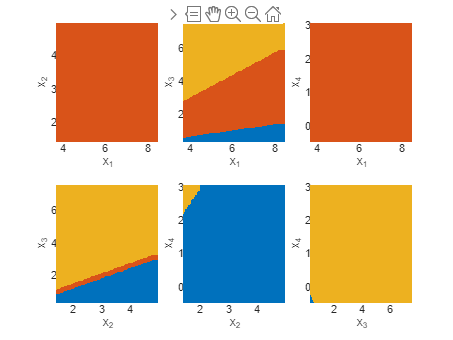



%%%%%%%%%%%%% Part(g) %%%%%%%%%%%%%%%%%%
% Plot each pair of feature in a subgraph

plot_decision_boundary([1 2],X_label_total,Y_label_total,theta,1)
plot_decision_boundary([1 3],X_label_total,Y_label_total,theta,2)
plot_decision_boundary([1 4],X_label_total,Y_label_total,theta,3)
plot_decision_boundary([2 3],X_label_total,Y_label_total,theta,4)
plot_decision_boundary([2 4],X_label_total,Y_label_total,theta,5)
plot_decision_boundary([3 4],X_label_total,Y_label_total,theta,6)


% part h
% f(0) will not change for the first one, therefore all change in second
% term. 
% second term is prob of a class - indicator function of class
% taking the sum of both sides for all k
% yields a probability of 1 on the left and a 1+0(k-1) on the right
% 1 - 1 = 0, therefore there will be no net change for each step

function plot_decision_boundary(indices,X,Y,theta,sub_fig_num)
% Plot decision boundary
X_plot = X(:,indices);
X1 = X_plot(Y==1, :);
X2 = X_plot(Y==2, :);
X3 = X_plot(Y==3, :);
% We will assign a color to each point in the mesh [x_min, x_max] x [y_min, y_max].
x_min = min(X_plot(:,1)) - 0.5;
x_max = max(X_plot(:,1)) + 0.5;
y_min = min(X_plot(:,2)) - 0.5;
y_max = max(X_plot(:,2)) + 0.5;
mesh_step_size = 0.05;
[xx,yy] = meshgrid(x_min:mesh_step_size:x_max,y_min:mesh_step_size:y_max);
meshgrid_data = [reshape(xx,[],1),reshape(yy,[],1),ones(numel(xx),1)];
inner_product_mesh = meshgrid_data * theta([indices,end],:);
% If do not include constant in decision, use the two lines below instead
% meshgrid_data = [reshape(xx,[],1),reshape(yy,[],1)];
% inner_product_mesh = meshgrid_data * theta(var,:);
[~,predict_meshgrid_label] = max(inner_product_mesh,[],2);

subplot(2,3,sub_fig_num);
% Create a color map to match the color of each class
map = 1/255 * [0,114,189; 217,83,25;237,177,32];
colormap(map)
% Plot decision for each point on mesh
scatter(reshape(xx,[],1),reshape(yy,[],1),[],predict_meshgrid_label,'s','fill');
hold on 
% Plot original data points
% scatter(X1(:,1),X1(:,2),'o','fill','MarkerFaceColor','#0072BD','MarkerEdgeColor','k');
% scatter(X2(:,1),X2(:,2),'^','fill','MarkerFaceColor','#D95319','MarkerEdgeColor','k');
% scatter(X3(:,1),X3(:,2),'s','fill','MarkerFaceColor','#EDB120','MarkerEdgeColor','k');
xlim([x_min,x_max])
ylim([y_min,y_max])
xlabel(['x_',int2str(indices(1))]);ylabel(['x_',int2str(indices(2))]);
% axis equal;
end

function data_cov = Xcov(data)
% takes in an array of data (x1; x2; x3; ...)
% returns covariance of the data, dxd matrix
    % transpose data to fit old form, then transpose back for answer
    data = data';
    mean = XYmean(data);
    data_norm = (data(:, :) - mean);
    data_cov = 0;
    for i = 1:size(data_norm,2)
        data_cov = data_cov + data_norm(:,i)*transpose(data_norm(:,i));
    end
    data_cov = data_cov / size(data_norm,2);
    data_cov = data_cov';
end

function data_cov = Xmu_cov(data, meanX)
% takes in an array of data (x1; x2; x3; ...)
% returns covariance of the data, dxd matrix
    % transpose data to fit old form, then transpose back for answer
    data = data';
    meanX = meanX';
    data_norm = (data(:, :) - meanX);
    data_cov = 0;
    for i = 1:size(data_norm,2)
        data_cov = data_cov + data_norm(:,i)*transpose(data_norm(:,i));
    end
    data_cov = data_cov / size(data_norm,2);
    data_cov = data_cov';
end

function data_cov = XYcov(data1,data2)
% takes in 2 arrays of data
% returns covariance of the data
    mean1 = XYmean(data1);
    mean2 = XYmean(data2);
    data1_norm = (data1(:, :) - mean1);
    data2_norm = (data2(:, :) - mean2);
    data_cov = 0;
    for i = 1:size(data1_norm,2)
        data_cov = data_cov + data1_norm(:,i)*transpose(data2_norm(:,i));
    end
    data_cov = data_cov / size(data1_norm,2);
end

function e_cor_coeff = empCorrCoeff(data1, data2)
    cov12 = cov(data1,data2);
    var1 = var(data1);
    var2 = var(data2);
    e_cor_coeff = cov12 / sqrt(var1 * var2);
end

%???
function c_log_loss = c_log_loss(x, y, theta, lambda)
    % g(Θ) = f0(Θ) + ∑j=1->n fj(Θ)
    % f0(Θ)

    unique_lables = unique(y);
    m = size(unique_lables,1);
    n = size(x,1);
    
    %calc fzero
    fzero = 0;
    for i = 1:m
        normthetal2 = power(norm(theta(:,i)),2);
        fzero = fzero + normthetal2;
    end
    %fzero_grad = fzero * 2 * lambda
    
    %∑j=1->n fj(Θ)
    fjtheta = 0;
    %fjtheta_grad = 0
    for i = 1:n
        sum1 = 0;
        for j = 1:m
            %theta(:,j)
            %x(n,:)
            sum1 = sum1 + exp(theta(:,j)'*x(i,:)');
        end
    
        sum2 = 0;
        for j = 1:m
            if y(i) == j
                %theta(:,j)
                %x(n,:)
                sum2 = sum2 + 1*theta(:,j)'*x(i,:)';
            end
            %if (theta(:,j)'*x(n,:)') == m
            %    sum2 = sum2 + 1
            %end
        end
        fjtheta = fjtheta + log(sum1) - sum2;
    end
    c_log_loss = fzero * lambda + fjtheta;
end

function pkxjTHETA = pkxjTHETA_calc(theta, xj_ext, k)
% function takes full theta, specific xj_ext, k to be calculated
    m = size(theta,2);
    sum_denom = 0;
    for l = 1:m
        %theta(:,l)
        %theta(:,l)'
        %xj_ext'
        %theta(:,l)'*xj_ext'
        sum_denom = sum_denom + exp(theta(:,l)'*xj_ext');
    end
    pkxjTHETA = exp(theta(:,k)'*xj_ext') / sum_denom;
    if pkxjTHETA < 10^-10
        pkxjTHETA = 10^-10;
    end
end


%modified from HW4
function CCR = CCR(x, label, theta)
% function takes 2 data sets, w and b
% returns the correct classification rate of the data using +/-w and b

    n = size(x,1);
    m = size(theta,2);
    x_ext = [x ones(size(x,1),1)];

    
    % check CCR for w
    correct = 0;
    for j = 1:n
        yguess = zeros(1,m);
        xj = x_ext(j,:)';
        for l = 1:m
            yguess(1,l) = theta(:,l)' * xj;
        end
        [~,yj] = max(yguess);
        yactual = label(j,1);
        if yj == yactual
            correct = correct + 1;
        end
    end
    CCR = correct / n;
end


function conf_mat = conf_mat(x, label, theta)
% function takes 2 data sets, w and b
% returns the correct classification rate of the data using +/-w and b
% returns a confusion matrix where the rows are the predicted rows and the
% columns are the correct columns
    n = size(x,1);
    m = size(theta,2);
    x_ext = [x ones(size(x,1),1)];
    unique_lables = unique(label);
    conf_mat = zeros(size(unique_lables,1));
    
    % calc conf map
    for j = 1:n
        yguess = zeros(1,m);
        xj = x_ext(j,:)';
        for l = 1:m
            yguess(1,l) = theta(:,l)' * xj;
        end
        [~,yj] = max(yguess);
        yactual = label(j,1);
        conf_mat(yj,yactual) = conf_mat(yj,yactual) + 1;
    end
end
